clc; clear; close all;

## Load the dataset

if ~isfile('anemia.csv')
    error('Dataset file "anemia.csv" not found in the current directory.');
end
data = readtable('anemia.csv');

## Remove missing values

if any(ismissing(data))
    data = rmmissing(data);
    fprintf('Removed missing values. New sample size: %d\n', height(data));
end

## Feature and target selection

featureNames = {'Gender', 'Hemoglobin', 'MCH', 'MCHC', 'MCV'};
X = data{:, featureNames};      % Predictor matrix
Y = data.Result;                % Response vector

## Display dataset info

fprintf('📊 Dataset Overview:\n');

📊 Dataset Overview:


fprintf('Total Samples: %d\n', size(X, 1));

Total Samples: 1421


fprintf('Number of Features: %d\n\n', size(X, 2));

Number of Features: 5



tabulate(Y);

  Value    Count   Percent
      0      801     56.37%
      1      620     43.63%


## Split data into training and testing sets

cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
YTrain = Y(training(cv), :);
XTest = X(test(cv), :);
YTest = Y(test(cv), :);

fprintf('\n🧪 Training Samples: %d\n', size(XTrain, 1));


🧪 Training Samples: 995


fprintf('🧪 Testing Samples: %d\n', size(XTest, 1));

🧪 Testing Samples: 426


## Decision Tree Model

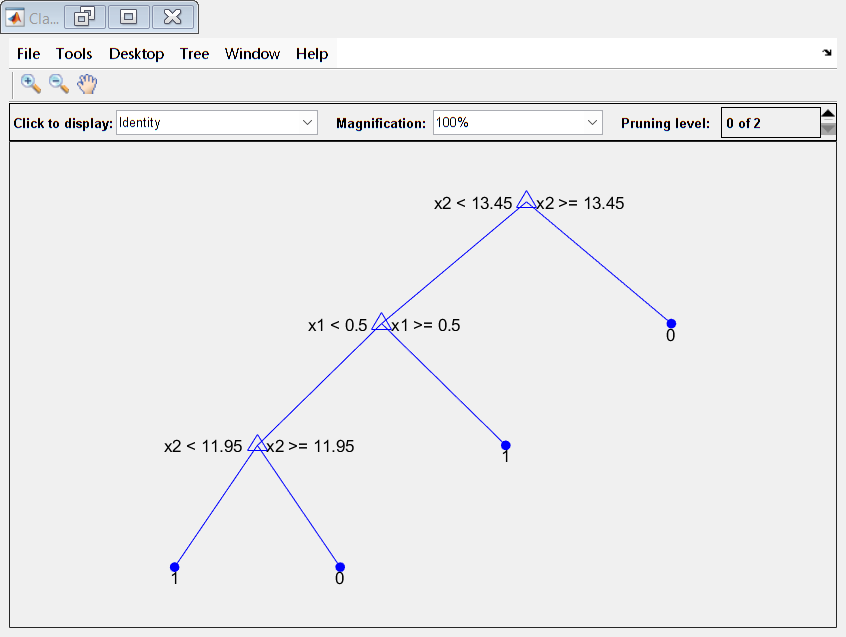

model = fitctree(XTrain, YTrain);
figure;
view(model, 'Mode', 'graph');

## Prediction and evaluation 

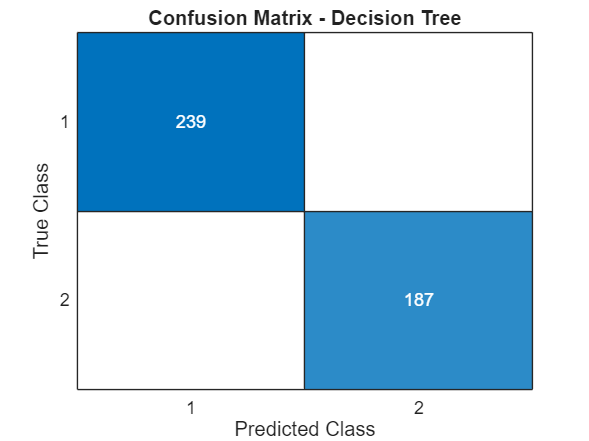

y_pred = predict(model, XTest);
confMat = confusionmat(YTest, y_pred);
figure;
confusionchart(confMat);
title('Confusion Matrix - Decision Tree');


accuracy = sum(y_pred == YTest) / numel(YTest);
precision = sum((y_pred == 1) & (YTest == 1)) / sum(y_pred == 1);
recall = sum((y_pred == 1) & (YTest == 1)) / sum(YTest == 1);
f1 = 2 * (precision * recall) / (precision + recall);

fprintf('\n📈 Decision Tree Performance:\n');


📈 Decision Tree Performance:


fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 100.00%


fprintf('Precision: %.2f\n', precision);

Precision: 1.00


fprintf('Recall: %.2f\n', recall);

Recall: 1.00


fprintf('F1-Score: %.2f\n', f1);

F1-Score: 1.00


##  5-fold cross-validation

cvModel = crossval(model, 'KFold', 5);
cvLoss = kfoldLoss(cvModel);
fprintf('Cross-Validation Loss (5-fold): %.4f\n', cvLoss);

Cross-Validation Loss (5-fold): 0.0000


## ROC Curve for Decision Tree

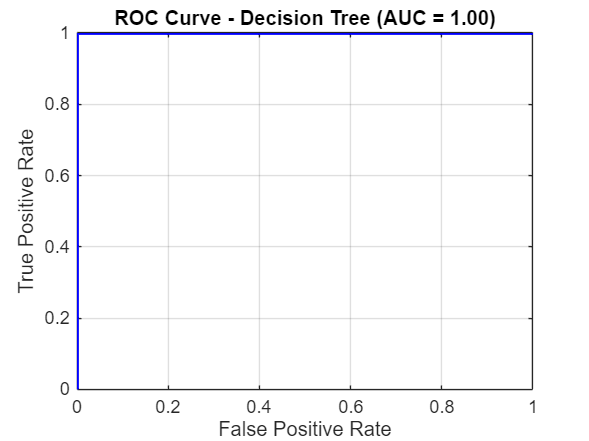

[~, scoresTree] = predict(model, XTest);
[fpRate, tpRate, ~, aucTree] = perfcurve(YTest, scoresTree(:, 2), 1);
figure;
plot(fpRate, tpRate, 'b-', 'LineWidth', 2);
xlabel('False Positive Rate'); ylabel('True Positive Rate');
title(sprintf('ROC Curve - Decision Tree (AUC = %.2f)', aucTree));
grid on;

## k-NN Model

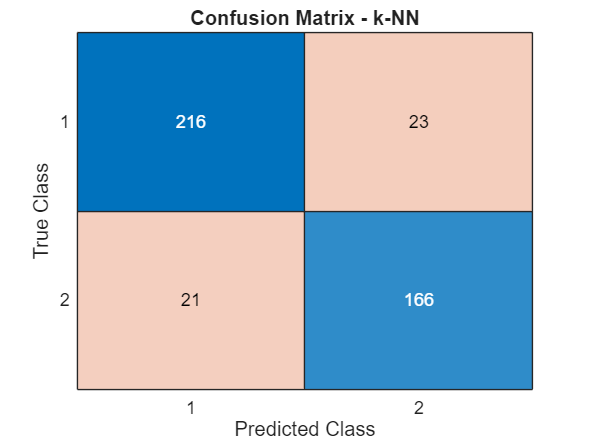

knnModel = fitcknn(XTrain, YTrain, 'NumNeighbors', 5);
knn_pred = predict(knnModel, XTest);

figure;
confusionchart(confusionmat(YTest, knn_pred));
title('Confusion Matrix - k-NN');


knn_accuracy = sum(knn_pred == YTest) / numel(YTest);
knn_precision = sum((knn_pred == 1) & (YTest == 1)) / sum(knn_pred == 1);
knn_recall = sum((knn_pred == 1) & (YTest == 1)) / sum(YTest == 1);
knn_f1 = 2 * (knn_precision * knn_recall) / (knn_precision + knn_recall);

fprintf('\n📊 k-NN Model Performance:\n');


📊 k-NN Model Performance:


fprintf('Accuracy: %.2f%%\n', knn_accuracy * 100);

Accuracy: 89.67%


fprintf('Precision: %.2f\n', knn_precision);

Precision: 0.88


fprintf('Recall: %.2f\n', knn_recall);

Recall: 0.89


fprintf('F1-Score: %.2f\n', knn_f1);

F1-Score: 0.88


## ROC for k-NN

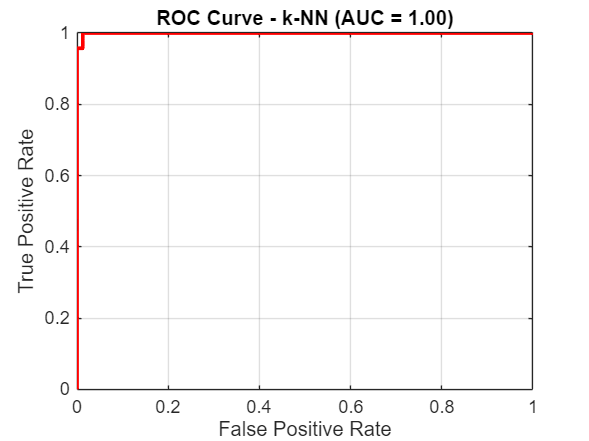

knnModel2 = fitcknn(XTrain, YTrain, ...
    'NumNeighbors', 5, ...
    'Distance', 'euclidean', ...
    'Standardize', true, ...
    'DistanceWeight', 'inverse', ...
    'ClassNames', [0 1]);

[~, knn_scores] = predict(knnModel2, XTest);
[fp_knn, tp_knn, ~, auc_knn] = perfcurve(YTest, knn_scores(:, 2), 1);
figure;
plot(fp_knn, tp_knn, 'r-', 'LineWidth', 2);
xlabel('False Positive Rate'); ylabel('True Positive Rate');
title(sprintf('ROC Curve - k-NN (AUC = %.2f)', auc_knn));
grid on;

##  Feature Importance

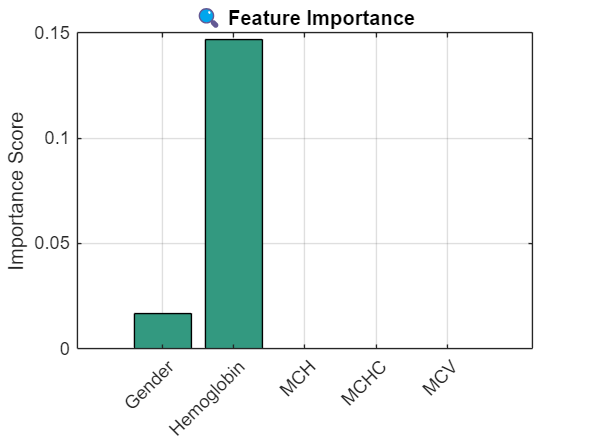

importance = predictorImportance(model);
figure;
bar(importance, 'FaceColor', [0.2 0.6 0.5]);
title('🔍 Feature Importance');
ylabel('Importance Score');
xticklabels(featureNames);
xtickangle(45);
grid on;

## Model Comparison

svmModel = fitcsvm(XTrain, YTrain);
rfModel = fitcensemble(XTrain, YTrain, 'Method', 'Bag');

models = {model, svmModel, knnModel, rfModel};
modelNames = {'Decision Tree', 'SVM', 'k-NN', 'Random Forest'};

fprintf('\n📊 Model Comparison:\n');


📊 Model Comparison:


for i = 1:length(models)
    y_hat = predict(models{i}, XTest);
    acc = sum(y_hat == YTest) / numel(YTest);
    fprintf('%-15s Accuracy: %.2f%%\n', modelNames{i}, acc * 100);
end

Decision Tree   Accuracy: 100.00%
SVM             Accuracy: 100.00%
k-NN            Accuracy: 89.67%
Random Forest   Accuracy: 100.00%


%% Save Model
save('anemia_decision_tree.mat', 'model');

%% Predict New Sample
newSample = [0, 9, 11, 11.2, 15];  % [Gender, Hemoglobin, MCH, MCHC, MCV]
prediction = predict(model, newSample);
fprintf('\n🔎 Prediction for new sample: %d (1=Anemic, 0=Normal)\n', prediction);


🔎 Prediction for new sample: 1 (1=Anemic, 0=Normal)


## Correlation Matrix

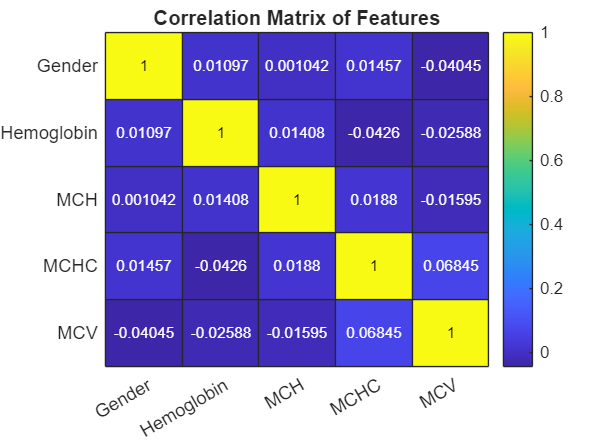

corrMatrix = corr(X);
figure;
heatmap(featureNames, featureNames, corrMatrix, 'Colormap', parula, 'ColorbarVisible', 'on');
title('Correlation Matrix of Features');

##  Data Visualization

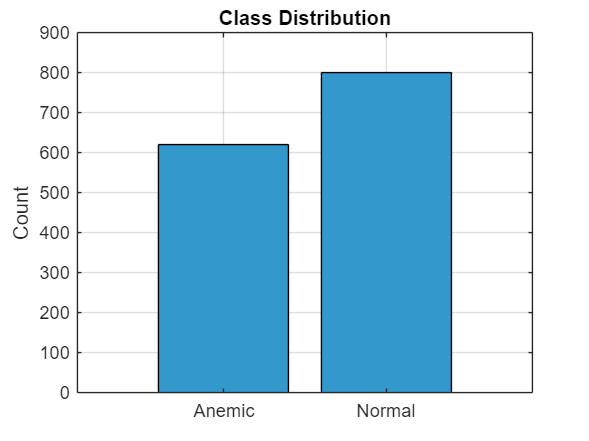

% Class Distribution
figure;
bar(categorical({'Normal','Anemic'}), groupcounts(Y), 'FaceColor', [0.2 0.6 0.8]);
title('Class Distribution');
ylabel('Count');
grid on;

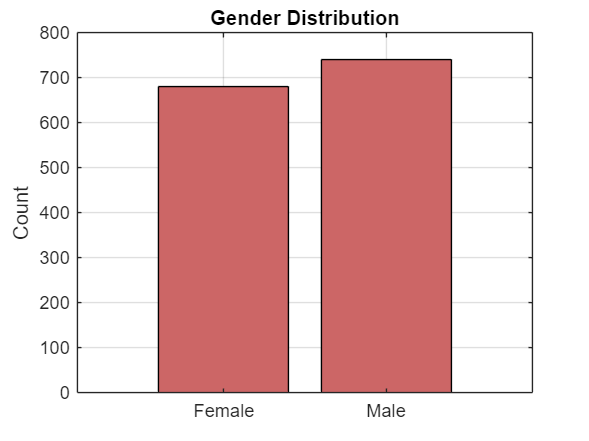


% Gender Distribution
figure;
bar(categorical({'Female','Male'}), groupcounts(data.Gender), 'FaceColor', [0.8 0.4 0.4]);
title('Gender Distribution');
ylabel('Count');
grid on;

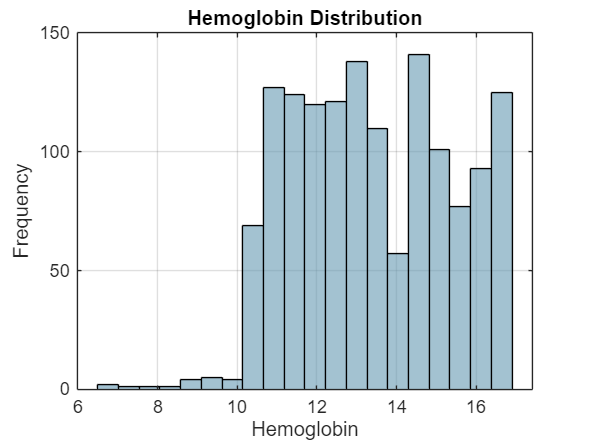

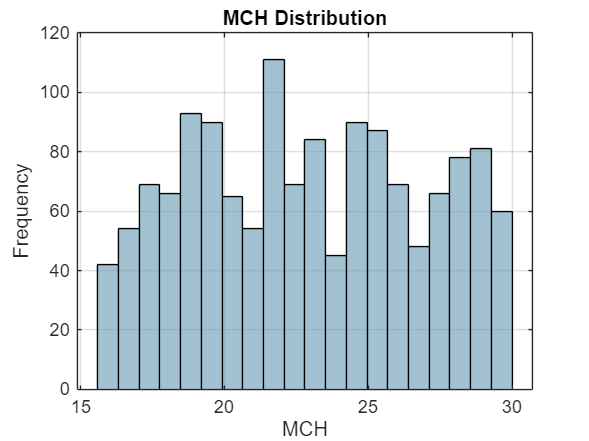

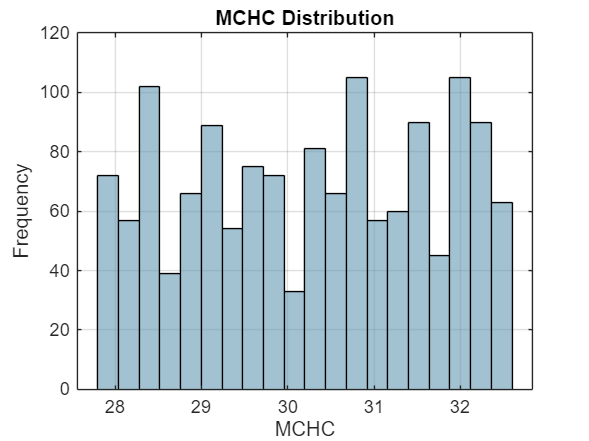

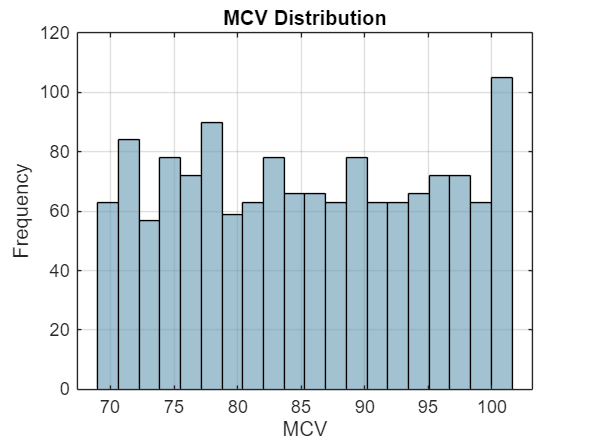


% Histogram of Parameters
params = {'Hemoglobin', 'MCH', 'MCHC', 'MCV'};
for i = 1:length(params)
    figure;
    histogram(data.(params{i}), 20, 'FaceColor', [0.4 0.6 0.7]);
    title([params{i} ' Distribution']);
    xlabel(params{i}); ylabel('Frequency');
    grid on;
end

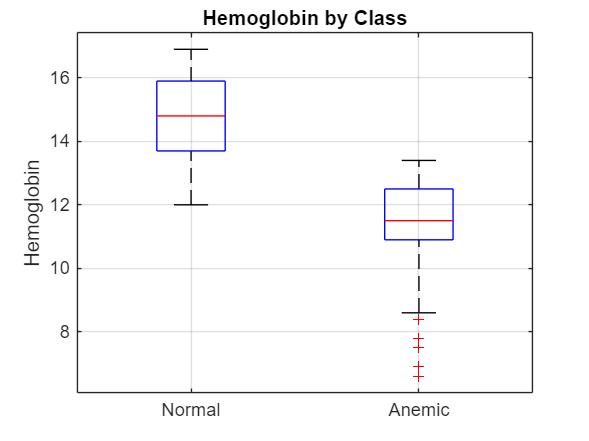

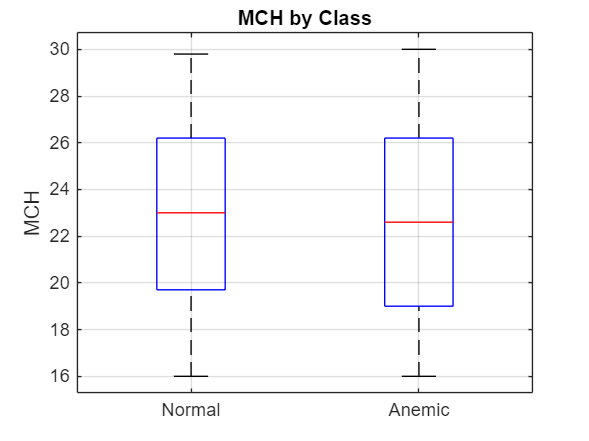

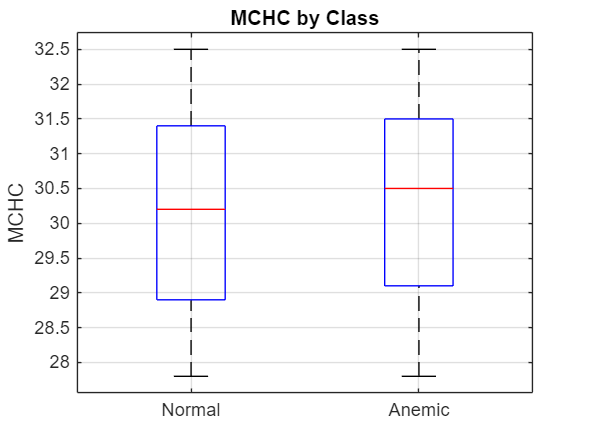

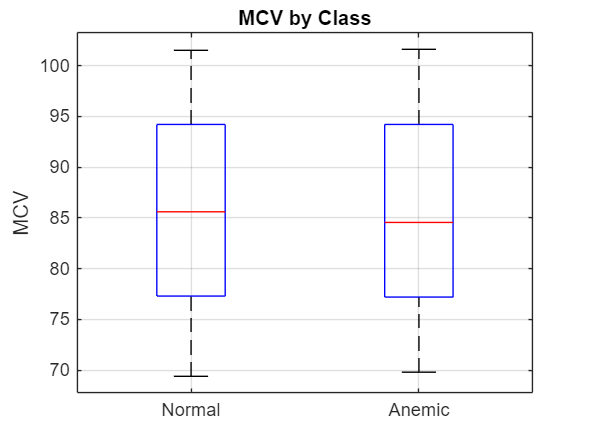


% Boxplots by Class
for i = 1:length(params)
    figure;
    boxplot(data.(params{i}), data.Result, 'Labels', {'Normal', 'Anemic'});
    title([params{i} ' by Class']);
    ylabel(params{i});
    grid on;
end

% Ensure the model is trained before this block
if exist('model', 'var')
    sample = input('Enter [Gender, Hemoglobin, MCH, MCHC, MCV] as a 1x5 numeric vector: ');
    
    if isnumeric(sample) && isrow(sample) && numel(sample) == 5
        class = predict(model, sample);
        fprintf('Predicted Class: %d (1=Anemic, 0=Normal)\n', class);
    else
        disp('❌ Invalid input. Please enter a numeric row vector with 5 elements.');
    end
else
    disp('❌ Error: The classification model "model" is not available.');
end

Predicted Class: 1 (1=Anemic, 0=Normal)


## Different types of anemia

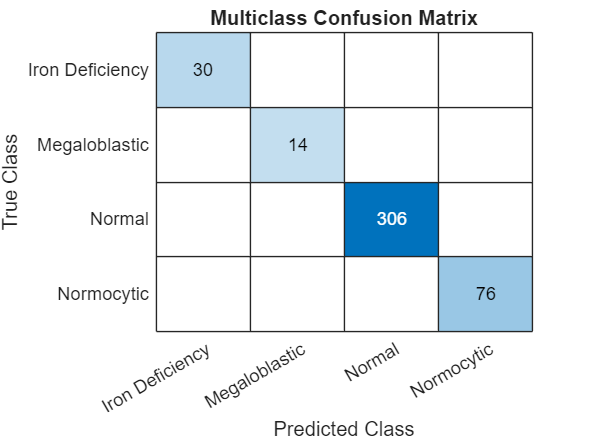

% Load dataset
data = readtable('anemia.csv');
data = rmmissing(data);

% Auto-label anemia types based on hematological rules
anemiaType = zeros(height(data), 1); % 0 = Normal

for i = 1:height(data)
    hb = data.Hemoglobin(i);
    mch = data.MCH(i);
    mchc = data.MCHC(i);
    mcv = data.MCV(i);

    if hb < 12
        if mcv < 80 && mch < 27 && mchc < 32
            anemiaType(i) = 1; % Iron Deficiency
        elseif mcv > 100
            anemiaType(i) = 2; % Megaloblastic
        else
            anemiaType(i) = 3; % Normocytic
        end
    else
        anemiaType(i) = 0; % Normal
    end
end

data.AnemiaType = anemiaType;

% Features and labels
featureNames = {'Gender', 'Hemoglobin', 'MCH', 'MCHC', 'MCV'};
X = data{:, featureNames};
Y = data.AnemiaType;

% Train-Test Split
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
XTrain = X(training(cv), :); YTrain = Y(training(cv), :);
XTest = X(test(cv), :); YTest = Y(test(cv), :);

% Train Decision Tree
model = fitctree(XTrain, YTrain, 'ClassNames', [0 1 2 3]);
save('anemia_multiclass_model.mat', 'model');

% Predict and Evaluate
y_pred = predict(model, XTest);
labels = {'Normal', 'Iron Deficiency', 'Megaloblastic', 'Normocytic'};

confMat = confusionmat(YTest, y_pred);
figure;
confusionchart(confMat, labels);
title('Multiclass Confusion Matrix');


acc = sum(y_pred == YTest) / numel(YTest);
fprintf('Overall Accuracy: %.2f%%\n', acc * 100);

Overall Accuracy: 100.00%


## Launch GUI app

function anemia_multiclass_GUI()
    fig = uifigure('Name', 'Anemia Type Predictor', 'Position', [100 100 700 500]);
    uilabel(fig, 'Text', 'Enter Patient Data', 'FontSize', 16, 'Position', [250 460 200 30]);

    % Gender Dropdown
    uilabel(fig, 'Text', 'Gender (0=F, 1=M):', 'Position', [50 400 120 22]);
    genderDrop = uidropdown(fig, 'Items', {'0', '1'}, 'Position', [180 400 100 22]);

    % Numeric Inputs
    paramNames = {'Hemoglobin', 'MCH', 'MCHC', 'MCV'};
    inputs = gobjects(1, length(paramNames));
    for i = 1:length(paramNames)
        uilabel(fig, 'Text', [paramNames{i} ':'], 'Position', [50 400 - i*40 100 22]);
        inputs(i) = uieditfield(fig, 'numeric', 'Position', [180 400 - i*40 100 22]);
    end

    % Predict Button
    uibutton(fig, 'Text', 'Predict & Generate Report', ...
        'Position', [280 80 180 30], ...
        'ButtonPushedFcn', @(btn, event) predictCallback());

    % Result Label
    resultLabel = uilabel(fig, 'Text', '', 'FontSize', 16, 'Position', [100 30 500 30], 'HorizontalAlignment', 'center');

    % Callback Function with Report Generator
    function predictCallback()
        try
            sample = [str2double(genderDrop.Value), ...
                      inputs(1).Value, inputs(2).Value, inputs(3).Value, inputs(4).Value];

            if any(isnan(sample))
                uialert(fig, 'Please enter all values.', 'Input Error');
                return;
            end

            % Load Model
            loaded = load('anemia_multiclass_model.mat', 'model');
            prediction = predict(loaded.model, sample);

            % Labels
            labels = {'Normal', 'Iron Deficiency', 'Megaloblastic', 'Normocytic'};
            resultText = ['Predicted: ' labels{prediction+1}];
            resultLabel.Text = resultText;

            % 🌟 Generate and Save Report
            reportFile = ['Anemia_Report_' datestr(now, 'yyyymmdd_HHMMSS') '.txt'];
            fid = fopen(reportFile, 'w');
            fprintf(fid, '--- Anemia Type Prediction Report ---\n');
            fprintf(fid, 'Date: %s\n\n', datestr(now));
            fprintf(fid, 'Input Data:\n');
            fprintf(fid, 'Gender: %d\n', sample(1));
            for j = 1:length(paramNames)
                fprintf(fid, '%s: %.2f\n', paramNames{j}, sample(j+1));
            end
            fprintf(fid, '\nPrediction Result:\n%s\n', resultText);
            fclose(fid);

            % 📊 Generate Visualization
            fig2 = figure('Visible', 'off');
            bar(sample(2:end));
            set(gca, 'xticklabel', paramNames);
            title('Patient Hematological Parameters');
            ylabel('Value');
            grid on;
            imgName = ['anemia_plot_' datestr(now, 'yyyymmdd_HHMMSS') '.png'];
            saveas(fig2, imgName);
            close(fig2);

            % Optional: Display confirmation
            uialert(fig, sprintf('Report saved to:\n%s\n\nChart saved as:\n%s', reportFile, imgName), 'Report Generated');

        catch ME
            uialert(fig, ['Error: ' ME.message], 'Prediction Error');
        end
    end
end


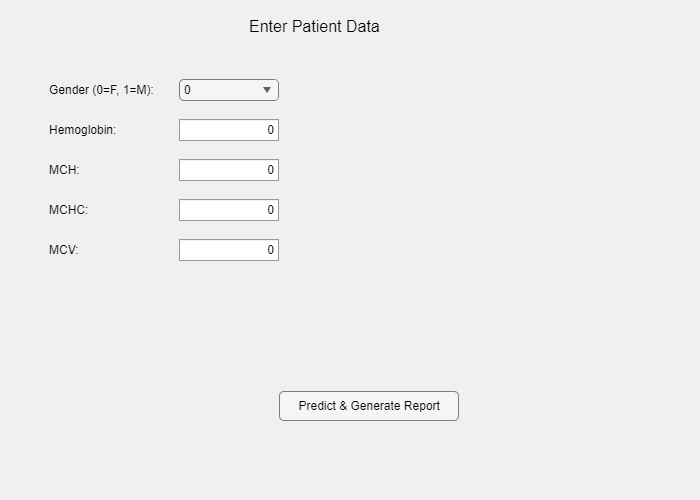

% Launch GUI
anemia_multiclass_GUI;